ЛАЧХ колебательного звена

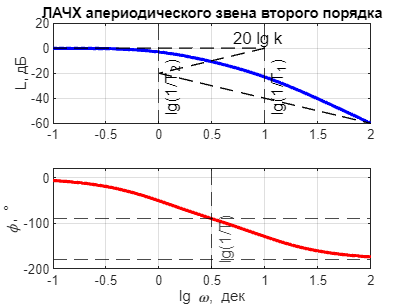

clear 
clc

% Параметры системы
k = 1;
T1 = 0.1;
T2 = 1;

% Передаточная функция
num = [0, 0, k];
den = conv([T1 1], [T2 1]);  % (T1*s + 1)(T2*s + 1)
sys = tf(num, den);

% Частотный диапазон
w = logspace(-1, 2, 1000);

% Построение ЛАЧХ
[mag, phase, wout] = bode(sys, w);
mag_db = 20*log10(squeeze(mag));
phase_deg = squeeze(phase);
omega = log10(wout);

% Построение графика
figure;
subplot(2,1,1)
plot(omega, mag_db, 'b', 'LineWidth', 2); hold on;
grid on;
ylabel('L, дБ');
title('ЛАЧХ апериодического звена второго порядка');
xline(log10(1/T1), '--k', 'lg(1/T_1)', 'LabelVerticalAlignment', 'bottom');
xline(log10(1/T2), '--k', 'lg(1/T_2)', 'LabelVerticalAlignment', 'bottom');
text(log10(0.5/T1), 20*log10(k), '20 lg k', 'VerticalAlignment', 'bottom');
% Добавим асимптоты
plot([omega(1) log10(1/T1)], [20*log10(k) 20*log10(k)], 'k--');
plot([log10(1/T1) log10(1/T2)], [20*log10(k) 20*log10(k) - 20], 'k--');
plot([log10(1/T2) omega(end)], [20*log10(k) - 20, 20*log10(k) - 20 - 20*(omega(end) - log10(1/T2))], 'k--');
ylim([-60 20]);

subplot(2,1,2)
plot(omega, phase_deg, 'r', 'LineWidth', 2); hold on;
grid on;
ylabel('\phi, °');
xlabel('lg \omega, дек');
xline(log10(1/sqrt(T1*T2)), '--k', 'lg(1/T)', 'LabelVerticalAlignment', 'bottom');
yline(-90, '--k');
yline(-180, '--k');
ylim([-200 20]);

ЛАЧЧ колебательного звена


$$J\ddot{\phi}\left(t\right) + 2b\dot{\phi}\left(t\right)+c\phi\left(t\right) = M\left(t\right)$$



$$W\left(s\right)=\frac{k}{T^2 s^2 +\xi \textrm{Ts}+1}$$


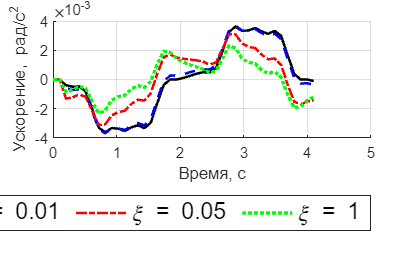

clear all
clc

load("decrement.mat")


figure('Units', 'centimeters', 'Position', [5, 5, 30, 20]);  % x, y, width, height
hold on
plot(time, d005, '-k', 'LineWidth', 1.5);          % черная сплошная
plot(time, d01, '--b', 'LineWidth', 1.5);          % синяя пунктирная
plot(time, d05, '-.r', 'LineWidth', 1.5);          % красная штрихпунктир
plot(time, d1, ':g', 'LineWidth', 2);              % зеленая точечная
xlabel("Время, с");
ylabel("Ускорение, рад/c^2");
grid on
lgd = legend("\xi = 0.005", "\xi = 0.01", "\xi = 0.05", "\xi = 1");
lgd.Orientation = 'horizontal';
lgd.Location = 'southoutside';
lgd.FontSize = 14;   % Увеличенный шрифт
exportgraphics(gcf, 'decrement.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');
exportgraphics(gcf, 'decrement.png', 'Resolution', 300, 'BackgroundColor', 'white');

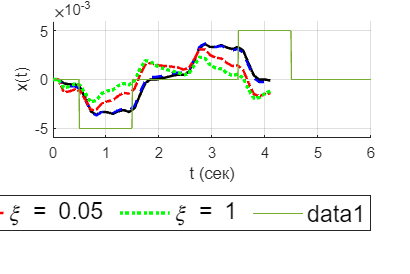

clear all
clc
% Временная ось
t = 0:0.01:6;

% Инициализируем x(t)
x = zeros(size(t));
M = 0.005;
% Задаём участки
x(t < 0.5) = 0;
x(t < 1.5 & t >= 0.5) = -M;
x(t >= 1.5 & t < 3.5) = 0;
x(t >= 3.5 & t < 4.5) = M;
x(t >= 4.5) = 0;

% Построение графика
plot(t, x)
xlabel('t (сек)')
ylabel('x(t)')
grid on
ylim([-M*1.2 M*1.2])

## Гироскоп

Omega_e=7.2921159e-5; 
phi_spb=deg2rad(59.95)

phi_spb = 1.0463


omega_spb = Omega_e * sin(phi_spb)

omega_spb = 6.3120e-05

f = 100;
n = 2*60*60*100

n = 720000

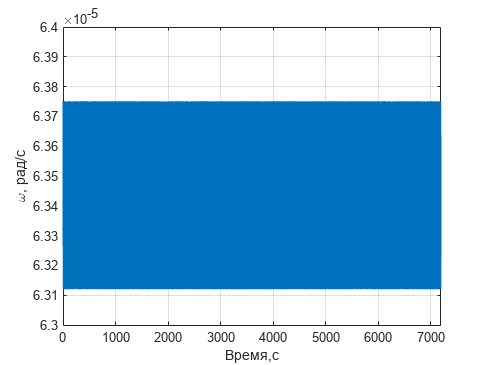

T = 1/f;
t = (0:n-1)/f;
sigma_test = omega_spb*0.01;

noise= sigma_test .* rand(n,1);

gyroData = omega_spb+noise;

figure


plot(t, gyroData)
grid on
xlabel("Время,с")
ylabel("\omega, рад/c")
ylim([6.3e-5 6.4e-5])
xlim([0 t(end)])
exportgraphics(gcf, 'gyroEarth.pdf', 'ContentType', 'vector', 'BackgroundColor', 'white');
exportgraphics(gcf, 'gyroEarth.png', 'Resolution', 300, 'BackgroundColor', 'white');


gyro_mean = mean(gyroData)

gyro_mean = 6.3435e-05

gyro_var = var(gyroData)

gyro_var = 3.3182e-14


omega_corr = gyro_mean - omega_spb

omega_corr = 3.1535e-07


rmse = sqrt(omega_corr^2+gyro_var)

rmse = 3.6418e-07


dt=T;

% 1) Forward-разность
%   δa = (ω_i - ω_{i-1})/dt
rmse_acc_forward = sqrt(2) * sigma / dt;

% 2) Central-разность
%   δa = (ω_{i+1} - ω_{i-1})/(2*dt)
rmse_acc_central = sigma / (sqrt(2) * dt);

fprintf('RMSE ускорения (forward) = %.3e rad/s^2\n', rmse_acc_forward)

RMSE ускорения (forward) = 2.578e-05 rad/s^2


fprintf('RMSE ускорения (central) = %.3e rad/s^2\n', rmse_acc_central)

RMSE ускорения (central) = 1.289e-05 rad/s^2
